- Differential equation

- Ordinary differential equation

             
$$\frac{\mathrm{du}}{\mathrm{dx}}\;=\mathrm{cu}$$


          
$$L\;\frac{d^{2\;} u}{{\mathrm{dx}}^{2\;} }+g\;\mathrm{sin}\;u=0\;$$


  - Partial differential equation : multivariables

           
$$\frac{\partial {\;}^{2\;} u}{\partial \;x^{2\;} }+\frac{\partial {\;}^{2\;} u}{\partial \;y^{\;2} }=0\;$$


- Function in matlab

- function : saved in a program file

- anonymous function: mot saved in a program file

1) ex. Function 

       plot  the function $y\left(x\right)\;,x\in \left\lbrack 0,1\right\rbrack$

             
$$y\left(x\right)=x^{2\;} +3x+1\;$$


% example a function
clear all; clc;
% z = 10;
z = linspace(0,1,100);
LW = 'linewidth';
Value = KimTemp(z);  % call KimTemp
plot(z,Value,LW,2)

2) ex. Anonymous fucntion 

clear all;
Value = @(x)  x.^2+ 3*x +1;

x = linspace(0,1,100);
Kim = x.^2 + 3*x+1;
% x = linspace(0,1,100);
% plot(x,Value(x),'linewidth',2)
plot(x,Kim,'r')

- ODE45 -  First order

A numerical solver to an ordinary differential equation as            

                        
$$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)$$


in symbolic math, the command is 'dsolve', nut the numerical solver are many command as

 ode15 , ode23,  ode45 depending the accuracy and so on. in general, at present, 'ode45' is good.

1) ex. the numerical solution

     
$$\frac{\mathrm{dy}}{\mathrm{dt}}=-y^2 ,\;\;t\in \left\lbrack 0,5\right\rbrack ,y\left(0\right)=1$$


clear all
LW = 'linewidth';
tspan = [0 5];
y0 = 1;
[t,y] = ode45(@(t,y)-y^2,tspan,y0); 
plot(t,y,LW,2); grid on

% different initial conditions
y0 = -1:1;
[t,y] = ode45(@(t,y) -2*y, tspan, y0); % define anonymous
plot(t,y,LW,2); grid on

- ODE45 - linear system 

                
$$\dot{\;x} =\left\lbrack \begin{array}{cc}
0 & 1\\
-2 & -3
\end{array}\right\rbrack x$$


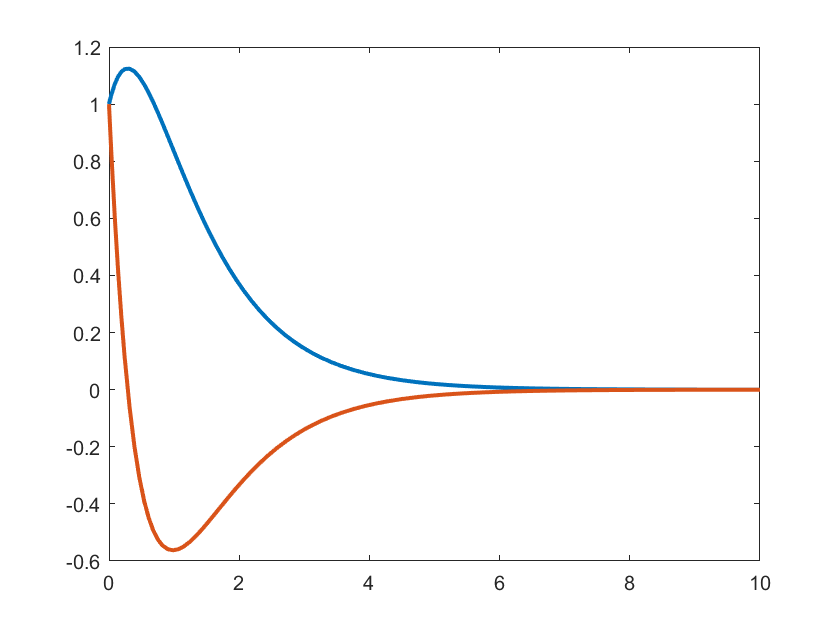

clear all
LW = 'linewidth';
tspan = [0 10];   % time domain
iniCon = [1;1];
f = @(t,x) [x(2);-2*x(1)-3*x(2)];    % define anonymous
[t, x] = ode45(f, tspan, iniCon);
plot(t,x,LW,2)

Plotting the phase plane

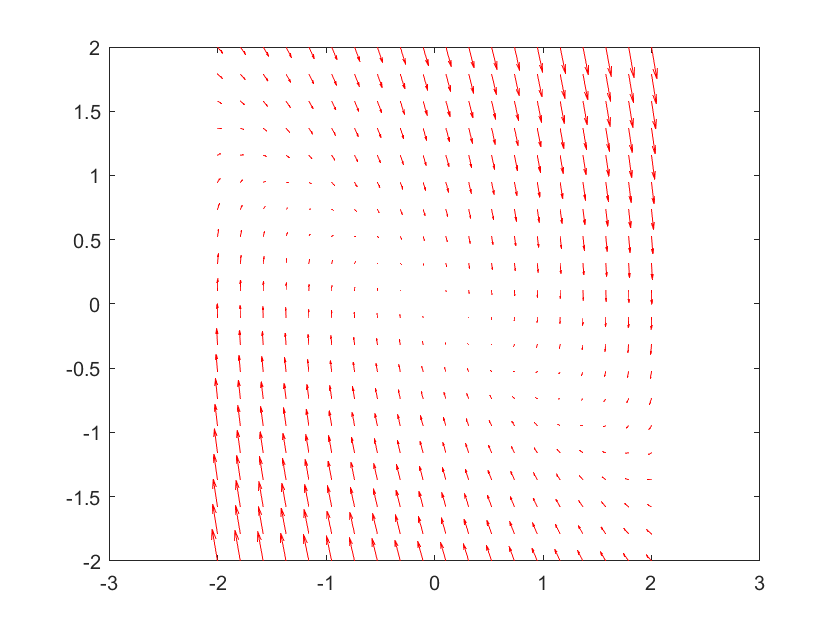

x1 = linspace(-2,2,20);
x2 = linspace(-2,2,20);
[x,y] = meshgrid(x1,x2);

% computing the vector field
u = zeros(size(x));
v = zeros(size(y));

% the derivative at every meshgrid point
t =0;
for i = 1:numel(x)
    dy =f(t,[x(i); y(i)]);
    u(i)= dy(1);
    v(i)= dy(2);
end

% plot the phase plane
quiver(x,y,u,v,'r');
hold on

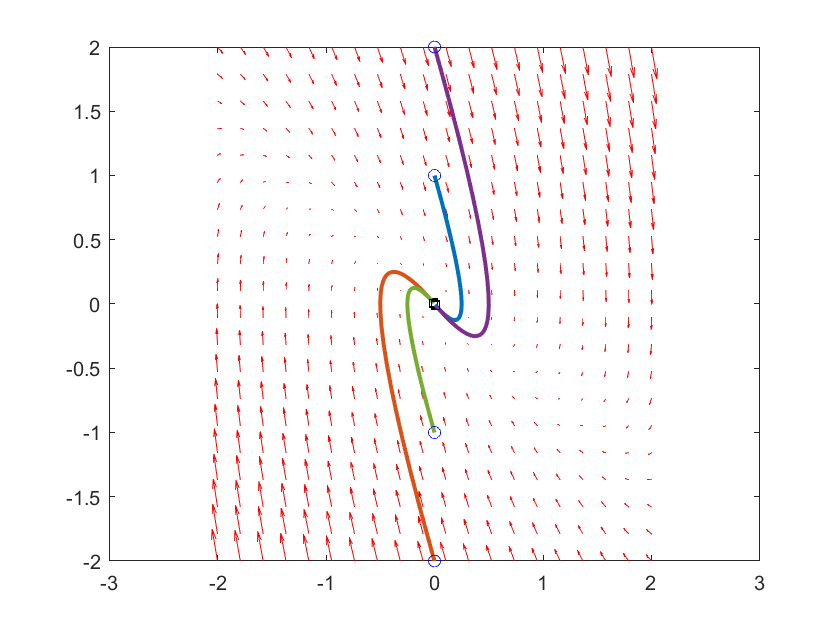


% plot the trajectories with different initial points
for y20 = [-2 -1 1 2]   % initial values
    [ts,ys] = ode45(f,[0,5],[0;y20]);
    plot(ys(:,1),ys(:,2),'linewidth',2)
    plot(ys(1,1),ys(1,2),'bo')    % starting point
    plot(ys(end,1),ys(end,2),'ks') % ending point
end
hold off

- ODE45 - nonlinear system

                  
$${y^{\prime } }^{\prime } -\mu \left(1-y^2 \right)y^{\prime } +y=0$$


into state space

               
$$y_1^{\prime } =y_{2\;}$$


                
$$y_{2\;}^{\prime } =\mu \left(1-y_{1\;}^2 \right)y_2 -y_{1\;}$$


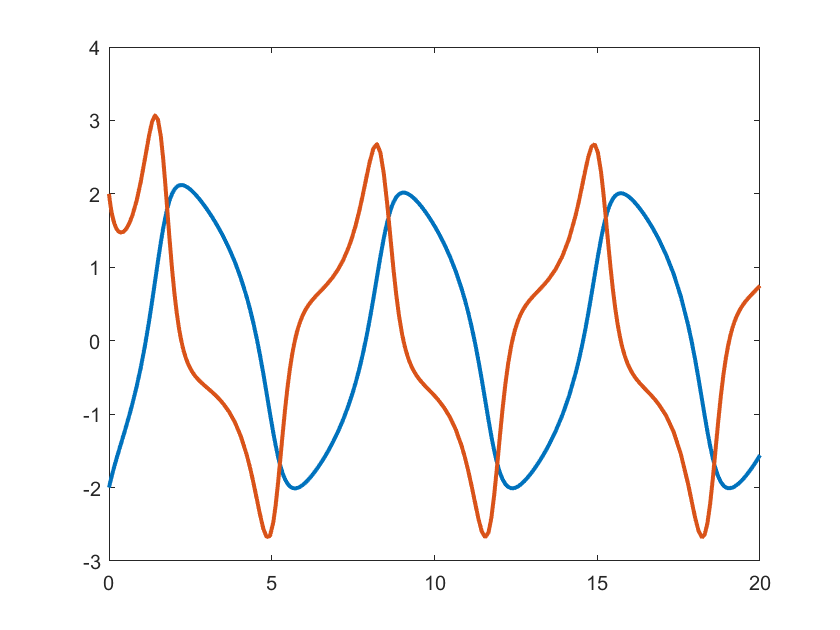

clear all
LW = 'linewidth';
tspan = [0 20];
iniCon = [-2;2];       % y1(0) = -2, y2(0) = 2
f = @(t,y) [y(2); (1-y(1)^2)*y(2)-y(1)];
[t, y] = ode45(f, tspan, iniCon);
plot(t,y,LW,2)

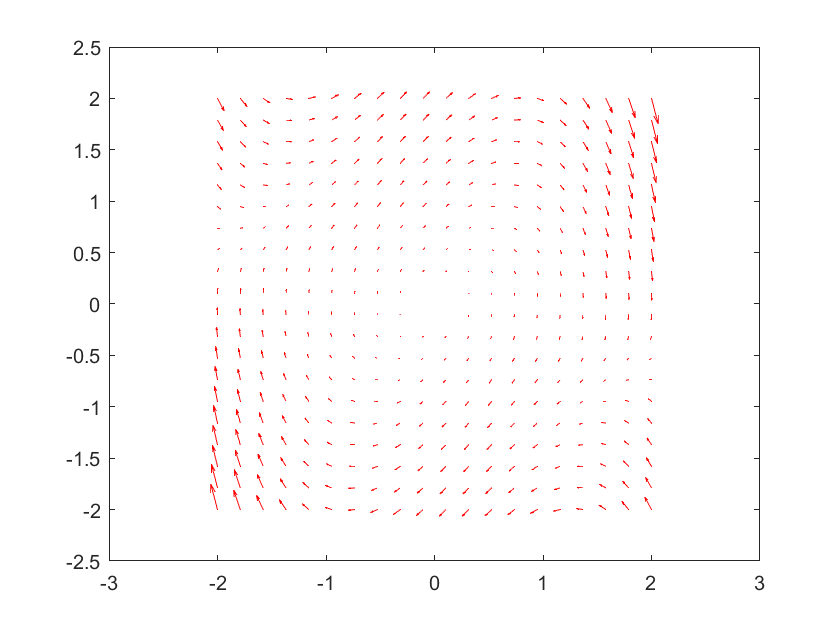

x1 = linspace(-2,2,20);
x2 = linspace(-2,2,20);
[x,y] = meshgrid(x1,x2);

% computing the vector field
u = zeros(size(x));
v = zeros(size(y));

% the derivative at every meshgrid
t =0;
for i = 1:numel(x)
    dy =f(t,[x(i); y(i)]);
    u(i)= dy(1);
    v(i)= dy(2);
end

% plot the phase plane
quiver(x,y,u,v,'r');
hold on

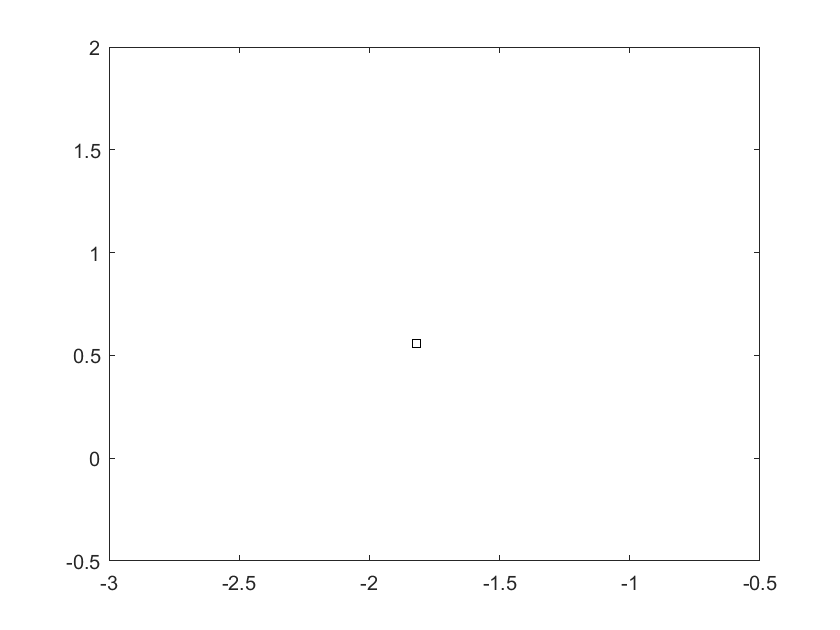


% plot the trajectories with different initial points
for y20 = [-2 -1 1 2]  
    [ts,ys] = ode45(f,[0,5],[0;y20]);
    plot(ys(:,1),ys(:,2),'linewidth',2)
    plot(ys(1,1),ys(1,2),'bo')    % starting point
    plot(ys( ...
end,1),ys(end,2),'ks') % ending point
end
hold off

function Value = KimTemp(x)
    Value  = x.^2+ 3*x +1; 
end